## SimpleUSBCameraTutorial.mlx is a template for future Fun-Robo USB Camera Code 

This is a simple color object tracking USB Camera Tutorial for your robots. 

*This example shows how to use the snapshot function to acquire live images from USB webcams. To use it you need to first load: *

***MATLAB Support Package for USB Webcams ****which provides the ability to bring *

*live images from any USB video class (UVC) compliant webcam into MATLAB. *

*Available USB webcam functions: *

- *webcamlist       - List of webams connected to your system *

- *webcam           - Connection to a webcam *

- *preview            - Preview live video data from webcam *

- *closePreview   - Close webcam preview window *

*Jessica Brown 2/14/2022 Revision 1*

clc                      % clear command window
clear                    % clear MATLAB workspace
imaqreset                % clear all image objects from memory

**Set up robot control system **( code that runs once ) 

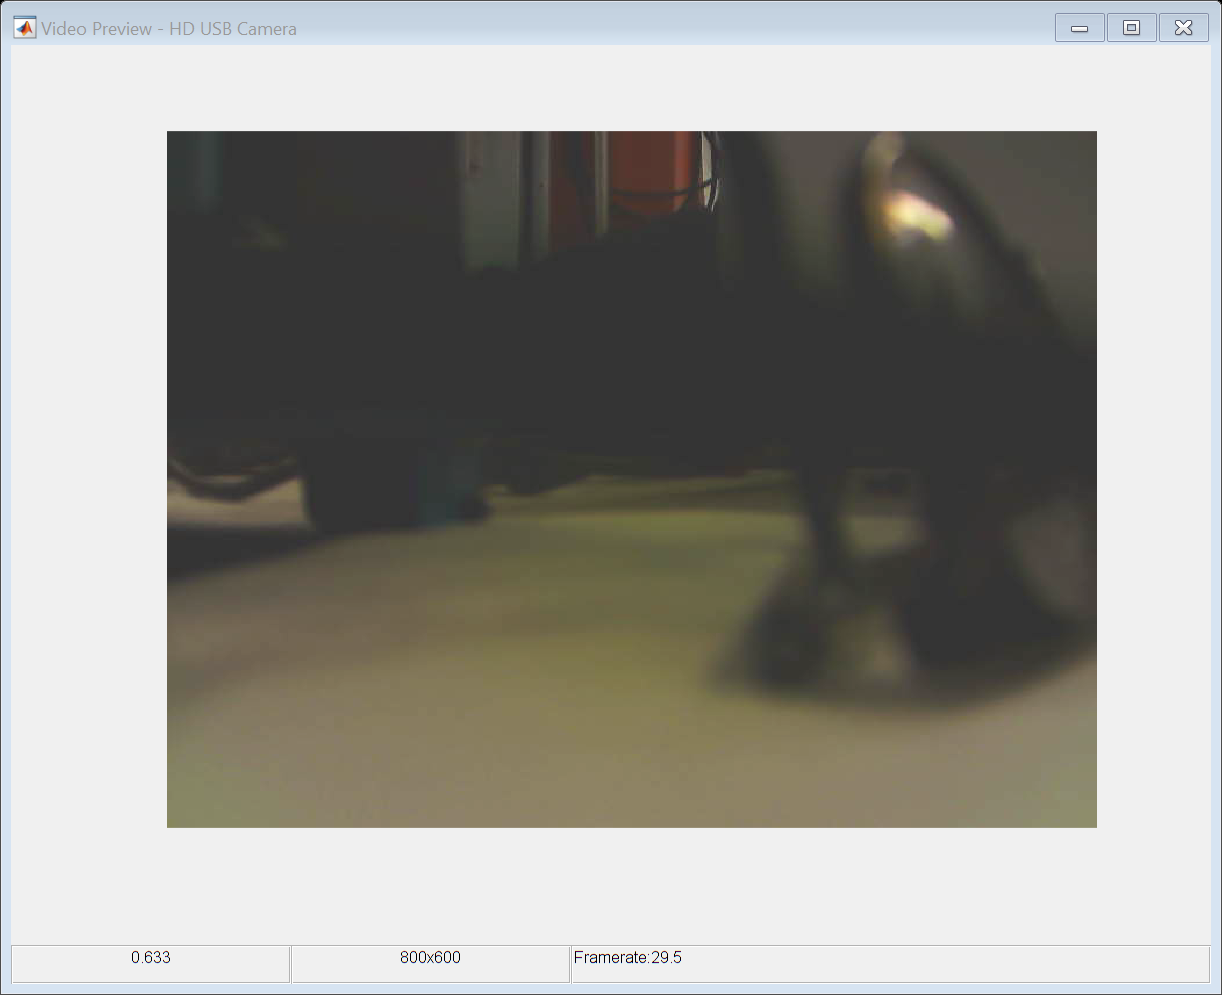

% Indentifying Available Webcams, The webcamlist function provides a cell
% array of all webcams on the current system that MATLAB can access.
% webcan(2) is hopefully {'Microsoft LifeCam Cinema'}, if not change code
% below

robotCam = setupCamera;

% Preview Video Stream
preview(robotCam)

% wave hand in front of lens to make sure camera is working
%gCamTest = input('move hand in front of camera, type G, then hit Enter ', 's');
%clc;

% close Preview window
%closePreview(robotCam);

r = rateControl(0.1); % create a 0.1 hz loop rate
reset(r) % reset loop time to zero

**Run robot control loop **( code that runs over and over ) 

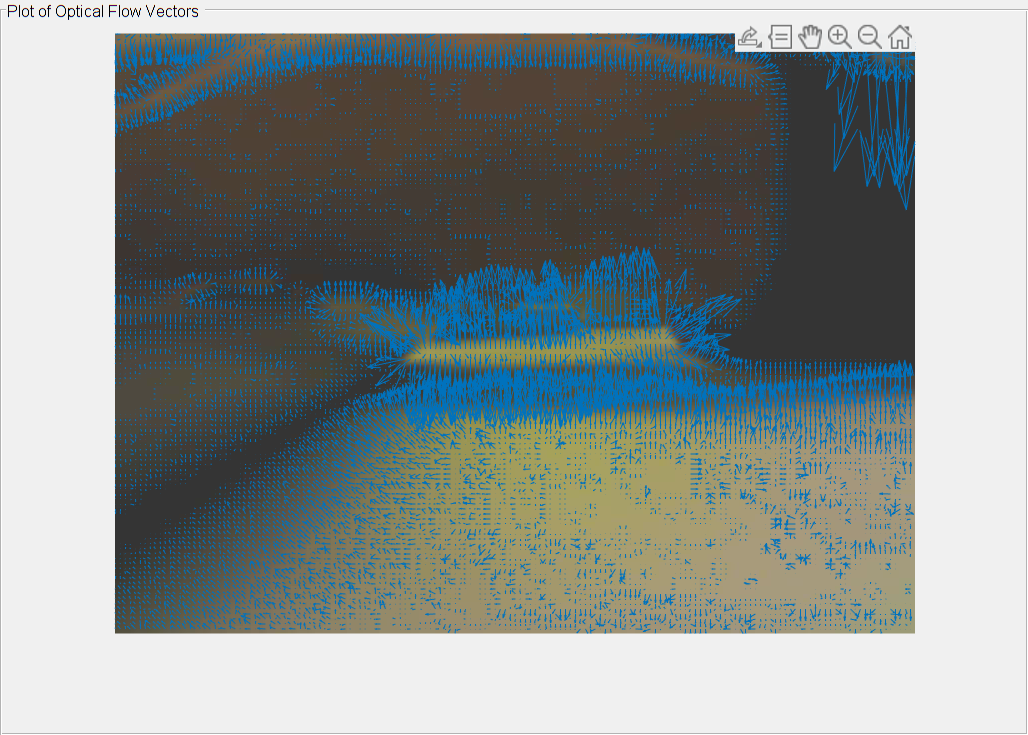

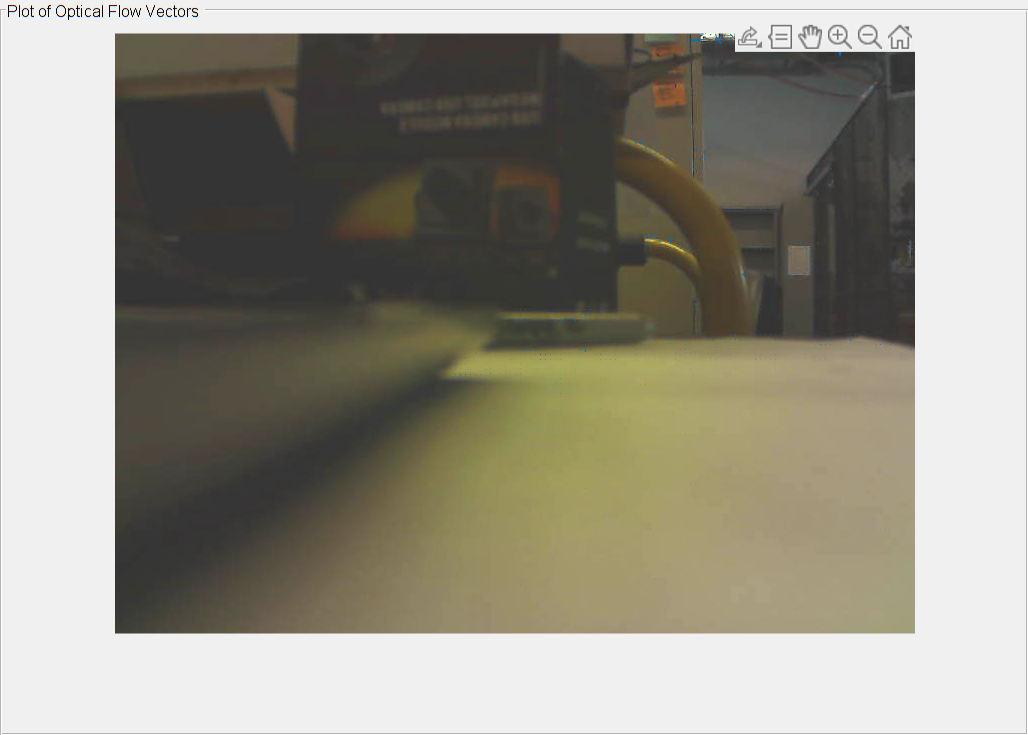

%%% TODO: Document all the code

controlFlag = 1; % create a loop control 
initialFrame = im2double(im2gray(snapshot(robotCam)));
nTests = 100;
threshold = 20;
of = opticalFlowHS;
of.Smoothness = 0.1;

% Capture flow magnitudes for each pixel over time
flowmat = zeros([size(initialFrame,1) size(initialFrame,2) nTests]);

% Create custom figure window to view optical flow vectors
h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

while (controlFlag < nTests + 1) % loop till ntests data captured

    robotRGB = snapshot(robotCam);
    robotIMG = im2gray(robotRGB); % take snapshot convert to grayscale
    flow = estimateFlow(of, robotIMG);
    
    % Save magnitudes of flow for post analysis
    flowmat(:,:,controlFlag) = flow.Magnitude;
    
    % Display RGB images and vectors for each pixel in real time
    imshow(robotRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',60,'Parent',hPlot);
    hold off

    % figure(camWindow) % go to camwindow to show new image 
    %image(robotIMG) % show image in camwindow figure 

    initialFrame = robotIMG;
    
    %waitfor(r); % wait for control loop cycle to complete
    controlFlag = controlFlag + 1; % increment loop 
end 

**Mission data processing **

For many robot applications, you will need to post-process the data collected after the mission.

% Goes through the flow matrices and filters out smaller magnitudes
for mat = 1:1:nTests
    for row = 1:1:size(flowmat(:,1,1))
        for col = 1:1:size(flowmat(1,:, 1)')
            if flowmat(row,col, mat) < 0.1
                flowmat(row, col, mat) = 0;
            end
        end
    end
end

% 
% %%% TODO: Find correlations between vectors in different blocks of image
% hold on;
% for image = 1:1:nTests
%     robotIMG = alphaList(:,:,image);
%     motion_temp = motion(:,:,image);
%     [X,Y] = meshgrid(1:blockSizeDim:size(robotIMG,2),1:blockSizeDim:size(robotIMG,1));
%     figure(image);
%     imshow(robotIMG);
%     hold on 
%     quiver(X(:),Y(:),real(motion_temp(:)),imag(motion_temp(:)),0)
%     hold off
%     savefig('test.fig');
% end



**Clean shut do**

Finally, with most embedded robot controllers, it's good practice to put all actuators into a safe position and then release all control objects and shut down all communication paths. This keeps systems from jamming when yoou want to run again.  

% Stop program and clean up the connection to WebCam 
% when no longer needed 

clc 
clear robotCam            % connection is no longer needed, clear the cam variable. 
disp('SimpleUSBCameraTutorial Done')
beep % play system to let user know program is ended

**Robot Functions **(store this codes local functions here)

In practice for modularity, readability and longevity, your main robot code should be as brief as possible and the bulk of the work should be done by functions 

function CONTROL_LOOP_INPUT(time)
    disp('robot running, cntrl-c to stop')
    fprintf('The loop time is %d, \n',time);
end